SimulationName='simulation_test_lifetime_distribution_20220715';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/';
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/'

cd(filepath)

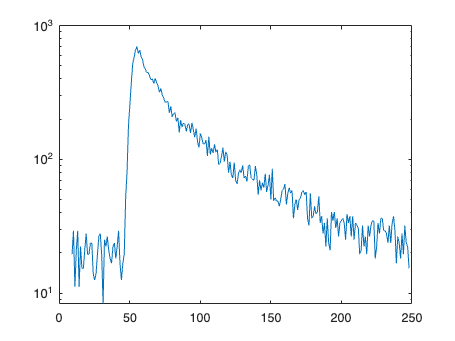

load('autofluorescence.mat')
AF=25487;
autofluorescence=AutoFluo0917*AF;

figure
semilogy(autofluorescence)

spc_openCurves('/Volumes/yaochen/Active/Pingchuan/2020FL/0922AKARFLEmx1Cre001/0922AKARFLEmx1Cre001FLIM016.mat',1)

Reading /Volumes/yaochen/Active/Pingchuan/2020FL/0922AKARFLEmx1Cre001/0922AKARFLEmx1Cre001FLIM016.mat


p1_PKA=spc.fits{1,1}.beta1/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p1_PKA = 0.6046

p2_PKA=spc.fits{1,1}.beta3/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p2_PKA = 0.3954

delta_peak_time=spc.fits{1,1}.beta5

delta_peak_time = 0.0791

SHG=spc.fits{1,1}.beta6

SHG = 1.6909e-04

lft_steps=(1:1:256)*12.5/256;
figureoffset=spc.switchess{1,1}.figOffset

figureoffset = 1.9758

% lft_steps(1:10)=0;
% lft_steps(247:256)=0;
weight_n_lft=lft_steps.*spc.lifetimes{1};
empirical_lft_PKA=sum(weight_n_lft)/sum(spc.lifetimes{1})

empirical_lft_PKA = 4.3575

samplesize_PKA=sum(spc.lifetimes{1})

samplesize_PKA = 816397

n_exp_PKA=spc.lifetimes{1};

% prf peak
load('prf_PKA.mat')
prf_peak_PKA=find(prf==max(prf))

prf_peak_PKA = 53

tau1_PKA=2.14

tau1_PKA = 2.1400

tau2_PKA=0.69

tau2_PKA = 0.6900

PKA_PopulationName='PKA_population_20220719'

PKA_PopulationName = 'PKA_population_20220719'

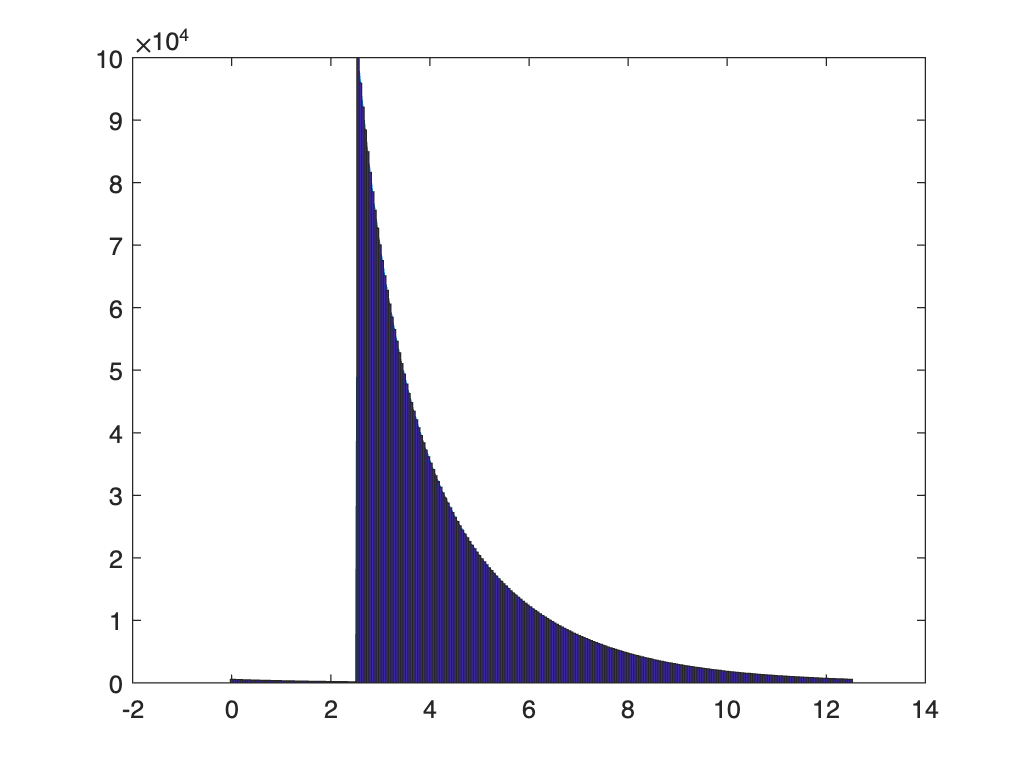

     3238761



GenPop256_Ach(100000,p1_PKA,p2_PKA,tau1_PKA,tau2_PKA,PKA_PopulationName,prf_peak_PKA)

save('PKA_simulation_parameters_20220719','tau1_PKA','tau2_PKA','p1_PKA','p2_PKA','samplesize_PKA','empirical_lft_PKA','n_exp_PKA','prf_peak_PKA')

mkdir([filepath,'/PKA_noauto_0719/']);

AF=25487; % autofluorescence size depending on the pixel numbers of the roi (autofluorescence photon of the whole view in total is 25487)

for j=1:50
    FLIMsim256_Ach_noauto(samplesize_PKA,0,AF,prf_peak_PKA,PKA_PopulationName, 'prf_PKA.mat', 'autofluorescence.mat'); % no DC
    load('FLIMSimulation_pm.mat')
    samplename=[filepath,'/PKA_noauto_0719/',num2str(j)];
    save(samplename,'n','xout');
end

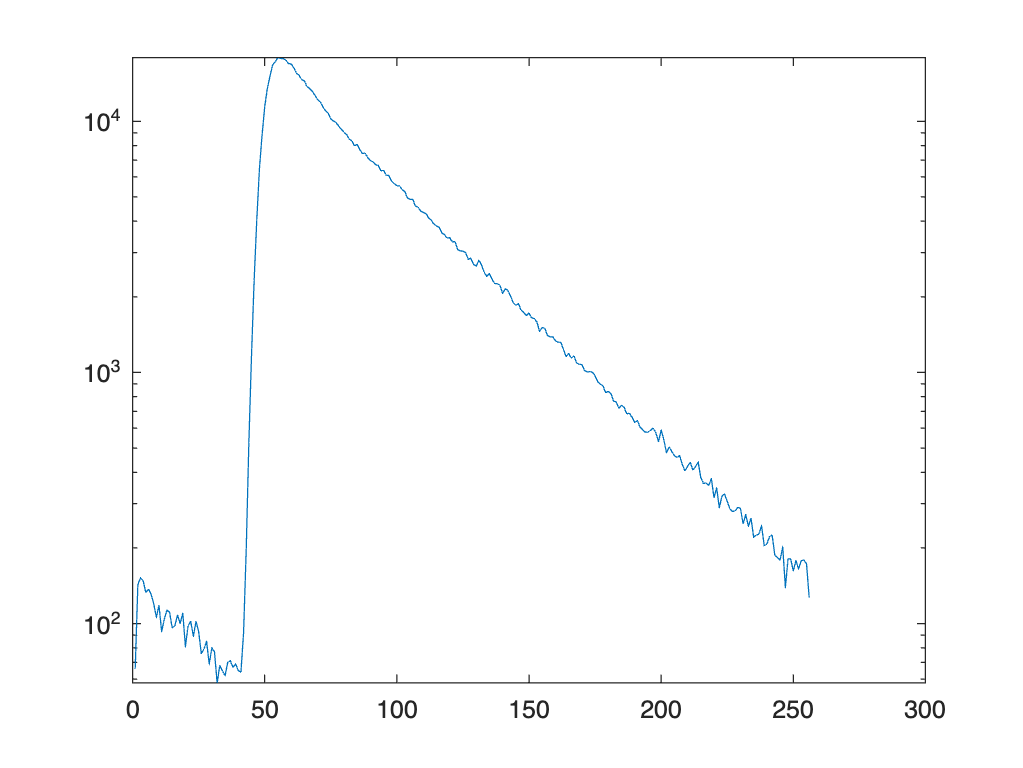

load([filepath,'/PKA_noauto/1.mat'])
figure
semilogy(n)

chan=1;
lft_steps=(1:1:256)*12.5/256;


    cd([filepath,'/PKA_noauto_0719/']);
    matfiles = dir('*.mat');
    
    p=[];
    TauTrunc=[];
    chi2=[];
    avgTau=[];
    emp_lft=[];
    emp_lftTrunc=[];
    
    
    for j=1:50
        filename = matfiles(j).name;
        load(filename);
        spc.lifetimes{1,1} = n;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        
        weight_n_lft=lft_steps.*n;
        empirical_lft=sum(weight_n_lft)/sum(n)-(delta_peak_time-spc.fits{1}.beta5); % prf peak at 53. 53*12.5/256=2.5879
        
        p(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3); %p1
        TauTrunc(j)=spc.fits{chan}.avgTauTrunc;%empirical lifetime; ; did not use spc_calcEmpiricalMean(chan) because the offset is not calculated every single time.
        chi2(j)=spc.fits{chan}.redchisq; %chi2
        avgTau(j)=spc.fits{chan}.avgTau; % mean Tau calculated from fit
        emp_lft(j)=empirical_lft; % empirical lft
        emp_lftTrunc(j)=spc.fits{chan}.EmpTauTrunc; %empTau truncated
    end

fraction of photons from SHG: 2.0774e-10
fraction of photons from SHG: 2.0785e-10
fraction of photons from SHG: 2.0783e-10
fraction of photons from SHG: 2.0784e-10
fraction of photons from SHG: 2.0767e-10
fraction of photons from SHG: 2.0755e-10
fraction of photons from SHG: 2.0763e-10
fraction of photons from SHG: 2.0782e-10
fraction of photons from SHG: 2.0782e-10
fraction of photons from SHG: 2.0769e-10
fraction of photons from SHG: 2.0779e-10
fraction of photons from SHG: 2.0766e-10
fraction of photons from SHG: 2.077e-10
fraction of photons from SHG: 2.0776e-10
fraction of photons from SHG: 2.0768e-10
fraction of photons from SHG: 2.0786e-10
fraction of photons from SHG: 2.0787e-10
fraction of photons from SHG: 2.0782e-10
fraction of photons from SHG: 2.0769e-10
fraction of photons from SHG: 2.0777e-10
fraction of photons from SHG: 2.0779e-10
fraction of photons from SHG: 2.076e-10
fraction of photons from SHG: 2.0784e-10
fraction of photons from SHG: 2.0776e-10
fraction of photon

    
    savename=[filepath,'simulation_result_PKA_20220719'];
    save(savename,'p','TauTrunc','chi2','avgTau','emp_lft','emp_lftTrunc');

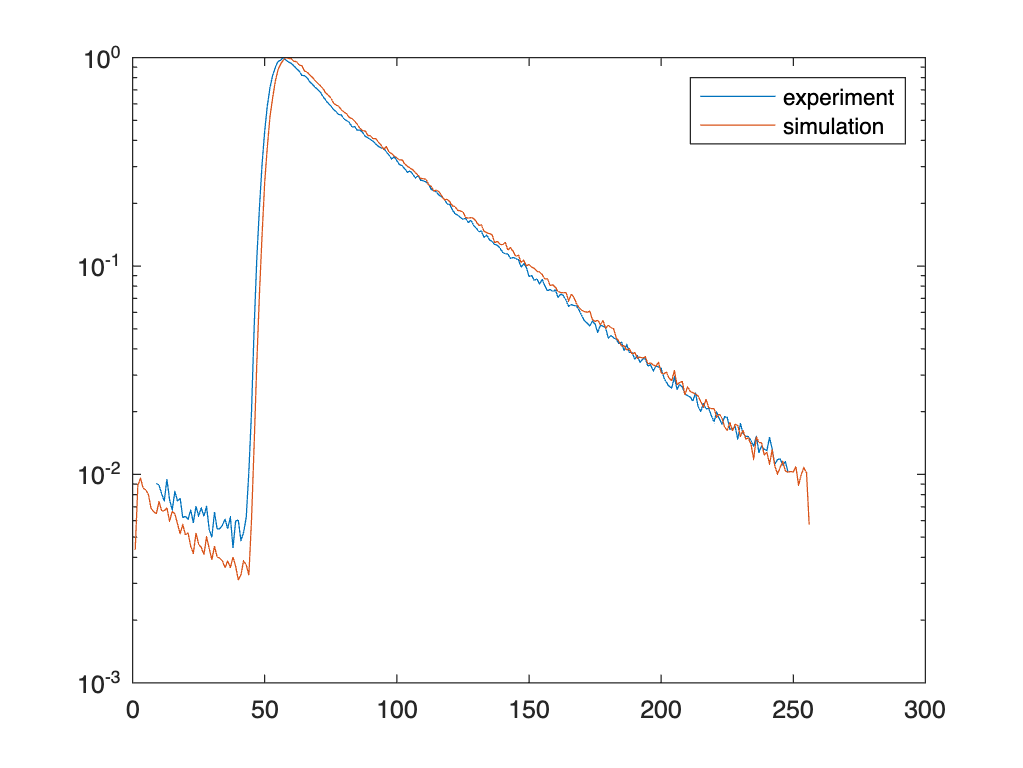

load('PKA_simulation_parameters_20220719.mat')
n_exp_PKA=n_exp_PKA/(max(n_exp_PKA));
load([filepath,'PKA_noauto_0719/1.mat'])
n_sim_PKA=n/max(n);

figure
semilogy(n_exp_PKA)
hold on
semilogy(n_sim_PKA)
legend('experiment','simulation')